% Programming Step 4: 4-bar Position At All Input Angles
%{
Joey Wyant, 09/09/2026
Machine Dynamics
%}
clc

a = 0.3; % Input link
b = 0.5; % Coupler link
c = 0.4; % Output link
d = 0.7; % Ground link
R_p = 0.3; % Coupler point vector magnitude

Theta_g = 0; % Ground off-set angle
Beta_p = 30; % Coupler point vector angle relative to coupler vector

% Calculate the Range of Motion of Theta2:
% In both configurations, the coupler and output links cannot subtract
% in-line. Therefore, there are a total of only two extreme positions:
% mirrored additive in-line coupler and output link.
Theta_2_max = round(acosd((d^2 + a^2 - (b + c)^2)/(2*d*a)), 2)

Theta_2_max = 123.2000

Theta_2_min = -1 * Theta_2_max

Theta_2_min = -123.2000


Theta_2_range = Theta_2_min:0.01:Theta_2_max;

% Open and crossed configuration arrays initialization
Theta_3_open = [];
Theta_4_open = [];
Theta_3_crossed = [];
Theta_4_crossed = [];
Px_open = [];
Py_open = [];
Px_crossed = [];
Py_crossed = [];

for i = 1:length(Theta_2_range)
    % Set value of theta 2 for this iteration
    Theta_2 = Theta_2_range(i);

    % Basket of Equations:
    K_1 = d/a;
    K_2 = d/c;
    K_3 = (a^2 - b^2 + c^2 + d^2)/(2*a*c);
    K_4 = d/b;
    K_5 = (c^2 - d^2 - a^2 - b^2)/(2*a*b);

    A = cosd(Theta_2) - K_1 - (K_2*cosd(Theta_2)) + K_3;
    B = -2*sind(Theta_2);
    C = K_1 - ((K_2 + 1)*cosd(Theta_2)) + K_3;
    D = cosd(Theta_2) - K_1 + (K_4*cosd(Theta_2)) + K_5;
    E = -2*sind(Theta_2);
    F = K_1 + ((K_4 - 1)*cosd(Theta_2)) + K_5;
    
    % Append calculations to lists
    Theta_3_open(i) = 2*atand((-E - (sqrt(E^2 - 4*D*F)))/(2*D));
    Theta_4_open(i) = 2*atand((-B - (sqrt(B^2 - 4*A*C)))/(2*A));
    Theta_3_crossed(i) = 2*atand((-E + (sqrt(E^2 - 4*D*F)))/(2*D));
    Theta_4_crossed(i) = 2*atand((-B + (sqrt(B^2 - 4*A*C)))/(2*A));

    Px_open(i) = a*cosd(Theta_2 + Theta_g) + R_p*cosd(Beta_p + Theta_3_open(i) + Theta_g);
    Py_open(i) = a*sind(Theta_2 + Theta_g) + R_p*sind(Beta_p + Theta_3_open(i) + Theta_g);
    Px_crossed(i) = a*cosd(Theta_2 + Theta_g) + R_p*cosd(Beta_p + Theta_3_crossed(i) + Theta_g);
    Py_crossed(i) = a*sind(Theta_2 + Theta_g) + R_p*sind(Beta_p + Theta_3_crossed(i) + Theta_g);
end

i_input10 = find(abs(Theta_2_range - 10) < 1e-6);

% Display
fprintf('Coupler Point Spot Check: Input Angle = 10 degrees\n');

Coupler Point Spot Check: Input Angle = 10 degrees



fprintf('Open configuration:\n');

Open configuration:


fprintf('Px = %.4f m\n', Px_open(i_input10));

Px = 0.3795 m


fprintf('Py = %.4f m\n', Py_open(i_input10));

Py = 0.3401 m



fprintf('Crossed configuration:\n');

Crossed configuration:


fprintf('Px = %.4f m\n', Px_crossed(i_input10));

Px = 0.5593 m


fprintf('Py = %.4f m\n', Py_crossed(i_input10));

Py = -0.0906 m


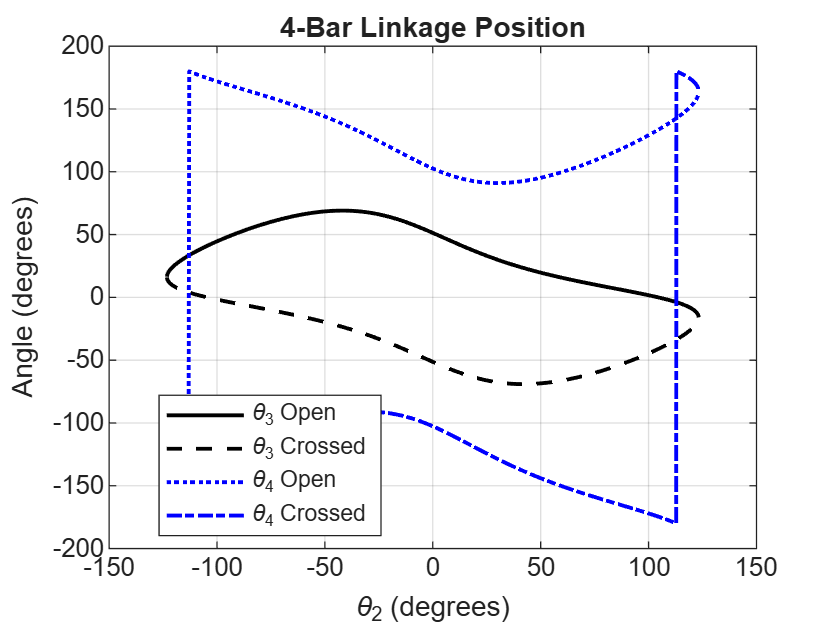


% Plots!
% Angle and Position
plot(Theta_2_range, Theta_3_open, 'k-', 'LineWidth', 1.5)
hold on
plot(Theta_2_range, Theta_3_crossed, 'k--', 'LineWidth', 1.5)
plot(Theta_2_range, Theta_4_open, 'b:', 'LineWidth', 1.5)
plot(Theta_2_range, Theta_4_crossed, 'b-.', 'LineWidth', 1.5)

xlabel('\theta_2 (degrees)')
ylabel('Angle (degrees)')
title('4-Bar Linkage Position')

legend('\theta_3 Open', '\theta_3 Crossed', '\theta_4 Open', '\theta_4 Crossed', 'Location', 'best')

grid on
hold off

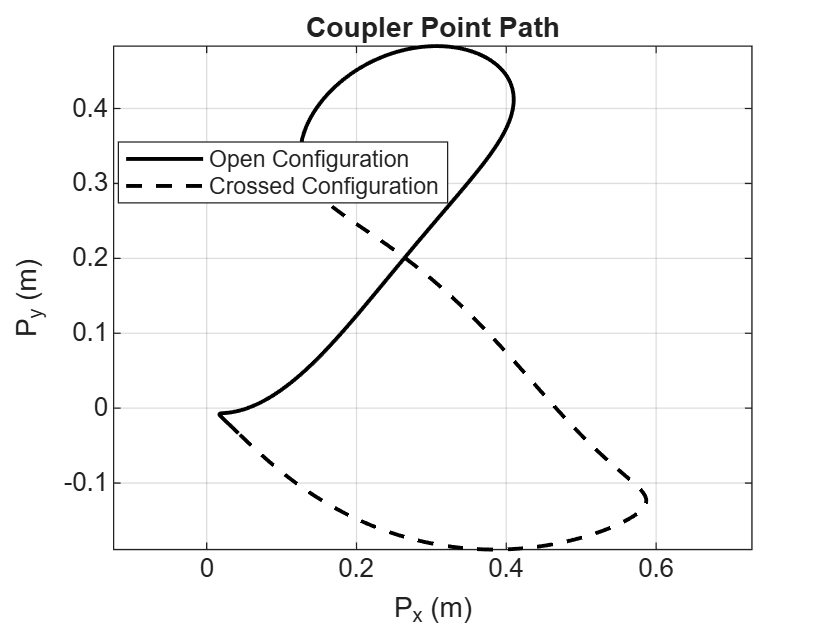


% Coupler Path
plot(Px_open, Py_open, 'k-', 'LineWidth', 1.5)
hold on
plot(Px_crossed, Py_crossed, 'k--', 'LineWidth', 1.5)

xlabel('P_x (m)')
ylabel('P_y (m)')
title('Coupler Point Path')

legend('Open Configuration', 'Crossed Configuration', 'Location', 'best')

axis equal
grid on
hold off